# **BUILDING SPAM CLASSIFIER TO CLASSIFY WHETHER EMAIL IS SPAM OR NOT**

## Load text data & Preprocess text using `string` methods and functions

clear the workspace and load the data (stored in email sample)

clear;
file = 'emailSample1.txt';
contents = fileread(file);

Process data

- Convert the content to string & convert all character to lower case

processed = string(contents);
processed = lower(processed);

- Strip HTML tags using `eraseBetween`

processed  = eraseBetween(processed,'<','>','Boundaries','inclusive');

- Replace dollar signs with 'dollar'

processed = replace(processed,"$","dollar");

- Split the email on whitespace into individual tokens (`contents` will become a `string` *array*)

processed = split(processed);

- Normalize URLs using `contains` and logical indexing

- Normalize email addresses and numbers, and remove punctuation using [`regexprep`](https://www.mathworks.com/help/matlab/ref/regexprep.html). 

processed(startsWith(processed,["http://","https://"])) =  "httpaddr";

processed = regexprep(processed,'.+@.+',"emailaddr"); 
processed = regexprep(processed,'[0-9]+',"number");
processed = regexprep(processed,'[^a-zA-Z0-9]',"");

- Remove empty or single character words using `strlength`

processed(strlength(processed)<=1) = [];

## Stemp the words in the string array

Word Stemming: Words are reduced to their stemmed form. For example, 'discount', 'discounts', 'discounted' and 'discounting' are all replaced with 'discount'. Sometimes, the Stemmer actually strips off additional characters from the end, so 'include', 'includes', 'included', and 'including' are all replaced with 'includ'.

Since `porterStemmer` was created for character arrays, we'll convert the elements of `contents` to character vectors before passing them to `porterStemmer`, then convert the output back into a `string`. 

processed = arrayfun(@(str)string(porterStemmer(char(str))),processed);

## Import the vocabulary list

The next step is to load the vocabulary words in vocab.txt. Since the file contains the (unneeded) word indices as well as the word list, we'll import the data into a `table` usng `readtable`, then select only the words by extracting the second column and converting it into a `string` array.

vocab = readtable('vocab.txt');
vocab = string(vocab{:,2});  

## Map the string array values to the vocabulary list

Run the code below to create a binary vector, `features` where `features(i)` equals `1` if `vocab(i)` appears in `processed` and 0 otherwise. The vocabulary list is then displayed alongside the feature vector in a `table`. To see what vocabulary words are in the email, hover the cursor over '`features`', click down arrow when it appears, then enter '1' for both the largest and smallest value to select between (or sort from largest to smallest). You should see the 48 words from the dictionary that were in found in the first spam email sample.

features = double(ismember(vocab,processed));
table(vocab,features)

ans = 1899×2 table
      vocab      features
    _________    ________
    "aa"            0    
    "ab"            0    
    "abil"          0    
    "abl"           0    
    "about"         0    
    "abov"          0    
    "absolut"       0    
    "abus"          0    
    "ac"            0    
    "accept"        0    
    "access"        0    
    "accord"        0    
    "account"       0    
    "achiev"        0    
    "acquir"        0    
    "across"        0    

All the steps above preprocess one email for classification process

size(features)

ans =         1899           1


Processed email has size [1899 1] this can be transposed to obtain size [1 1899]. Then a number of processed email can be concatenated to obtain [m 1899] training example.

The is case the training example (preprocessed email) was stored in spamTrain.mat file

## Train an SVM for spam classification using `fitclinear`

In this section we train an SVM classifier model for spam detection using the `fitclinear` function. As there are a large number of variables (1,899), the `fitclinear` function will offer improved performance over `fitcsvm`. 

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.31833 |     0.53747 |     0.31833 |     0.31833 |       5.8963 |
|    2 | Best   |    0.040833 |     0.17967 |    0.040833 |    0.055568 |   3.1012e-09 |
|    3 | Best   |    0.023333 |     0.18578 |    0.023333 |    0.042667 |    0.0098717 |
|    4 | Accept |      0.0375 |     0.17776 |    0.023333 |    0.023448 |     4.54e-07 |
|    5 | Accept |    0.040833 |     0.17986 |    0.023333 |    0.023358 |   6.6777e-08 |
|    6 | Accept |    0.039167 |     0.17745 |    0.023333 |    0.023364 |   0.00024566 |
|    7 | Accept |    0.025833 |     0.19242 |    0.023333 |    0.023429 |    0.0024391 |
|    8 | Accept |    

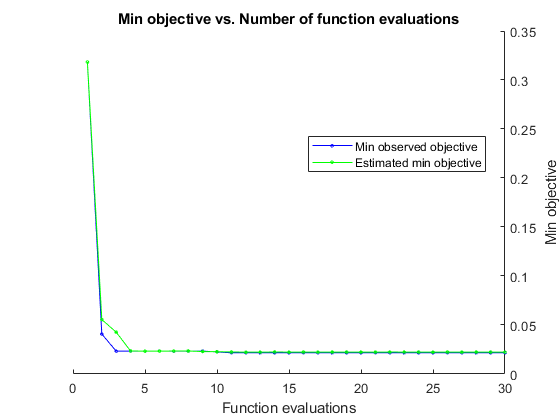

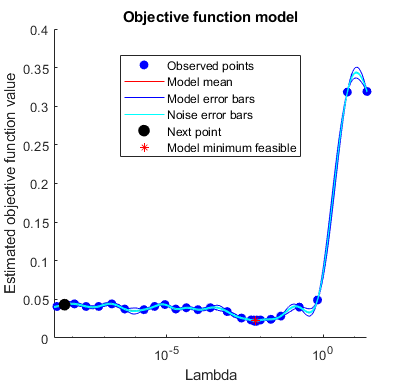


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 29.9426 seconds
Total objective function evaluation time: 6.0925

Best observed feasible point:
     Lambda 
    ________
    0.006357
Observed objective function value = 0.021667
Estimated objective function value = 0.022377
Function evaluation time = 0.18781

Best estimated feasible point (according to models):
     Lambda 
    ________
    0.006357
Estimated objective function value = 0.022377
Estimated function evaluation time = 0.19412



load spamTrain.mat;
opts = struct('Holdout',0.3);
linSVMmdl = fitclinear(X,y,'Learner','svm','Regularization','ridge','OptimizeHyperparameters',{'lambda'},'HyperparameterOptimizationOptions',opts);

% 
load('spamTest.mat');
fprintf('Training Accuracy: %f | Test Accuracy: %f\n',...
        mean(predict(linSVMmdl,X)==y)*100,...
        mean(predict(linSVMmdl,Xtest)==ytest)*100);

Training Accuracy: 99.625000 | Test Accuracy: 98.900000


## List the top predictors for spam

We print out the top predictor words as given by their score (model coefficient). The model coefficients are found in the `Beta` model property of a `classificationLinear` variable, which we combine with the vocabulary words into a `table` before sorting.

% Sort the weights and obtain the vocabulary list
tbl = table(vocab,linSVMmdl.Beta,'VariableNames',{'Word','Score'});
tbl = sortrows(tbl,'Score','descend')

tbl = 1899×2 table
       Word         Score 
    ___________    _______
    "click"         0.4312
    "remov"        0.37312
    "our"          0.35585
    "basenumb"     0.35055
    "guarante"     0.32414
    "visit"        0.28924
    "dollar"       0.25907
    "pleas"        0.24375
    "you"          0.23185
    "most"          0.2307
    "nbsp"         0.22376
    "multipart"    0.21806
    "will"         0.21591
    "enumb"        0.20302
    "credit"       0.20103
    "here"         0.20058

## Classify your own email 

We can use the code below to classify your own email or the try the sample provides

preprocess function processes the email for you. Then use the trained SVM model the classify the processed email.

yourEmail = '';
eml = 'spamSample2.txt';
processed = preprocess(eml);
features = ismember(vocab,processed);
if predict(linSVMmdl,double(features)')
    disp('This email is probably spam.')
else
    disp('This email is probably not spam.')
end

This email is probably spam.
